# **Ejemplo** - Sistema de filtrado de una piscina

*Adaptado del problema 8.49 Fox and McDonald's Intro to Fluid Mechanics, 10ed*

Una piscina tiene un sistema de filtración parcial. El agua a 75°F es bombeada desde la piscina hacia el sistema mostrado. La bomba entrega 30 gpm. Las tuberías son de PVC con un diámetro nominal de 3/4" (diámetro interno = 0.824"). La caída de presión a través del filtro se puede aproximar como Δp = 0.6 Q², donde Δp está en psi y Q está en gpm. Determine el aumento de presión en la bomba y el flujo a través de cada tubería.

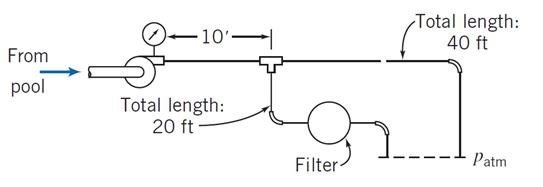

## Solución:

Continuidad: $Q_1 -Q_2 -Q_3 =0$

Conservación de la energía: $\begin{array}{l}
H_P -\left(h_{f_1 } +h_{K_1 } \right)-\left(h_{f_2 } +h_{K_2 } \right)=0\\
\left(h_{f_2 } +h_{K_2 } \right)-\left(h_{f_3 } +h_{K_3 } \right)=0
\end{array}$

Donde $h_{f_i } =f_i \frac{L_i }{D_i }\frac{V_i^2 }{2g}$, $H_P =\frac{\dot{W} }{\rho gQ_1 }$,  $h_K =\sum K\frac{V^2 }{2g}$ 

%% SOLUCIÓN DEL SISTEMA NO LINEAL
X0=[15 20 10];   % aproximación inicial de dp (psi), Q2 y Q3 (gpm)
X0=fsolve(@(x) piscina_filtro(x),X0);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


disp('Caudales (gpm):'); disp([30 X0(2) X0(3)]);

Caudales (gpm):
   30.0000   24.8544    5.1456



disp('Aumento de presión en la bomba (psi):'); disp(X0(1));

Aumento de presión en la bomba (psi):
   22.4520



function F = piscina_filtro(X)

%% DATOS CONOCIDOS
L=[10 40 20];               % longitudes, ft
D=[1 1 1]*0.824/12;         % diámetros, ft
eD=(4.9E-6)./D;             % rugosidad relativa (PVC)
rho=1.935;                  % densidad de agua @ 75F, slug/ft³
mu=1.91E-5;                 % viscosidad de agua @ 75F, slug/(ft*s)
g=32.17;                    % aceleración de la gravedad, ft/s²
K_codo=0.3; K_T=0.2;        % coeficientes de pérdidas
h_filtro=(0.6*X(3)^2)*144/(rho*g);  % pérdida en el filtro

%% DEFINIR VARIABLES
Q=zeros(1,3); Q(1)=30*0.002228; % caudal total, gpm -> ft³/s
Q(2:3)=X(2:3)*0.002228; % caudales, gpm -> ft³/s
Hp=144*X(1)/(rho*g);    % aumento de presión en la bomba, psi -> ft

%% VARIABLES SECUNDARIAS
Re=rho*4*Q./(pi*(mu)*D);                        % número de Reynolds
fD=(0.2479-0.0000947*(7-log10(Re)).^4)./...
    (log10(eD./3.615+7.366./Re.^0.9142)).^2;    % factor Darcy
hF=8*fD.*L.*Q.^2./(g*pi^2.*D.^5);               % pérdidas (Darcy–Weisbach)
hF=real(hF.*sign(Q));
V=Q./(pi/4*D.^2);                               % velocidades, ft/s   
K=[K_T K_codo 2*K_codo];                        % suma de coeficiente de pérdidas
hK=K.*V.^2./(2*g); hK(3)=hK(3)+h_filtro;        % pérdidas menores

%% ECUACIONES
F=[Q(1)-Q(2)-Q(3);...
    Hp-(hF(1)+hK(1))-(hF(2)+hK(2));...
    (hF(2)+hK(2))-(hF(3)+hK(3));];
end